## Case Study: Self-Organizing Sequential Search Rules

### Warren D. Craft

#### Based on class discussion and examples

#### in CS 533: Experimental Methods in CS

#### (Spring 2019, University of New Mexico, taught by A. Mueen and G. M. Fricke)

First, some slides from the related lecture (Spring 2019), …

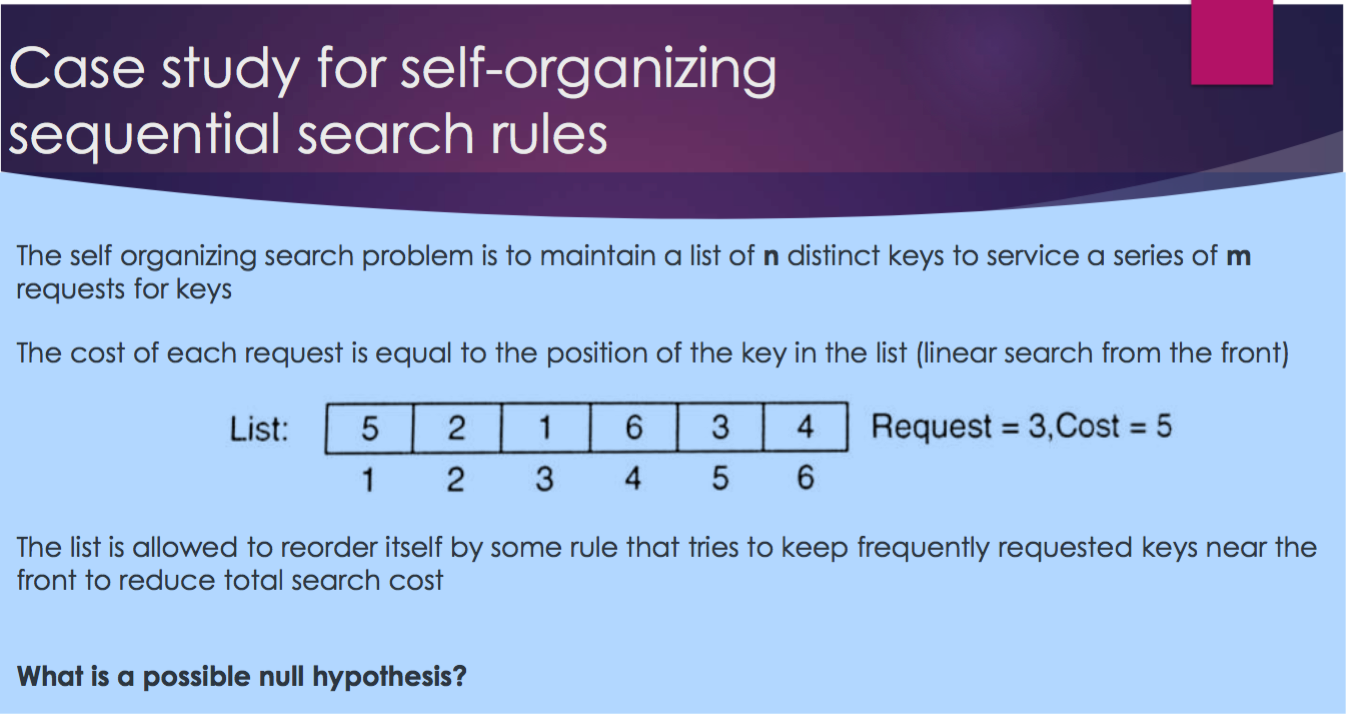  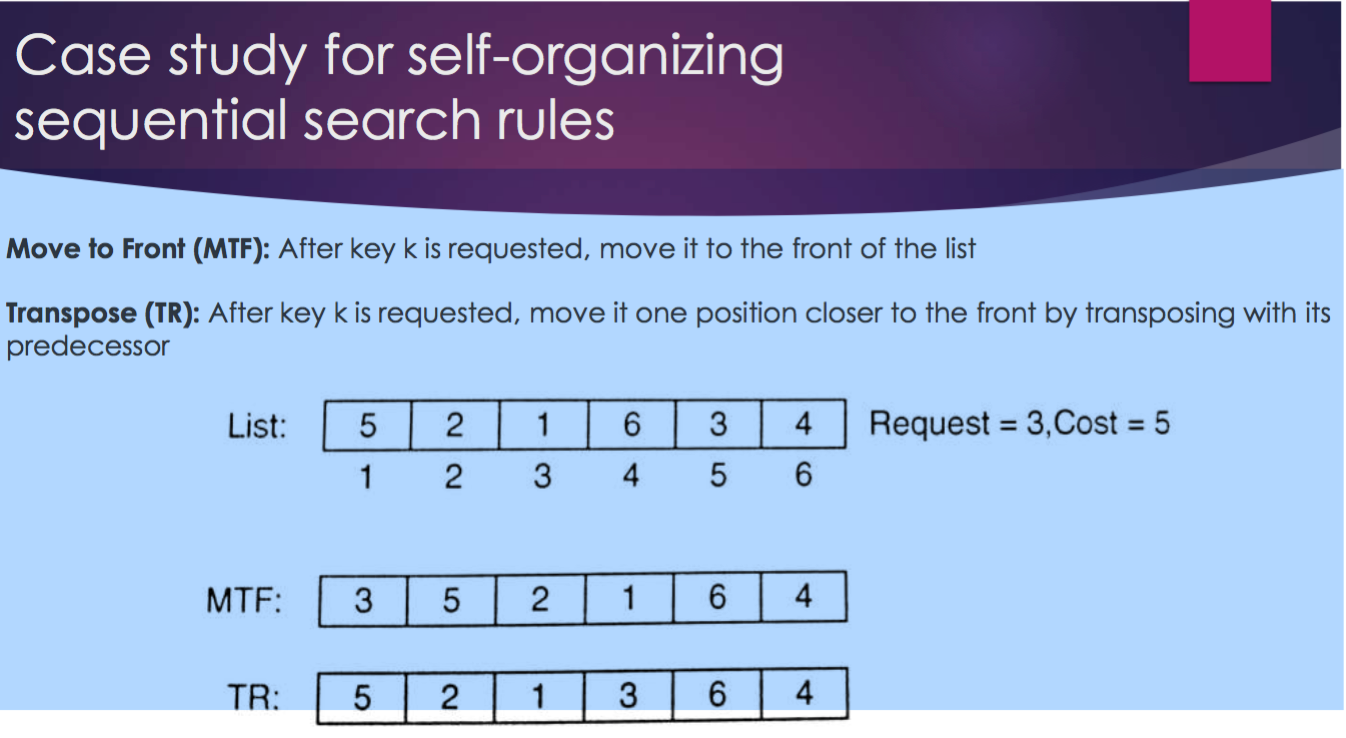

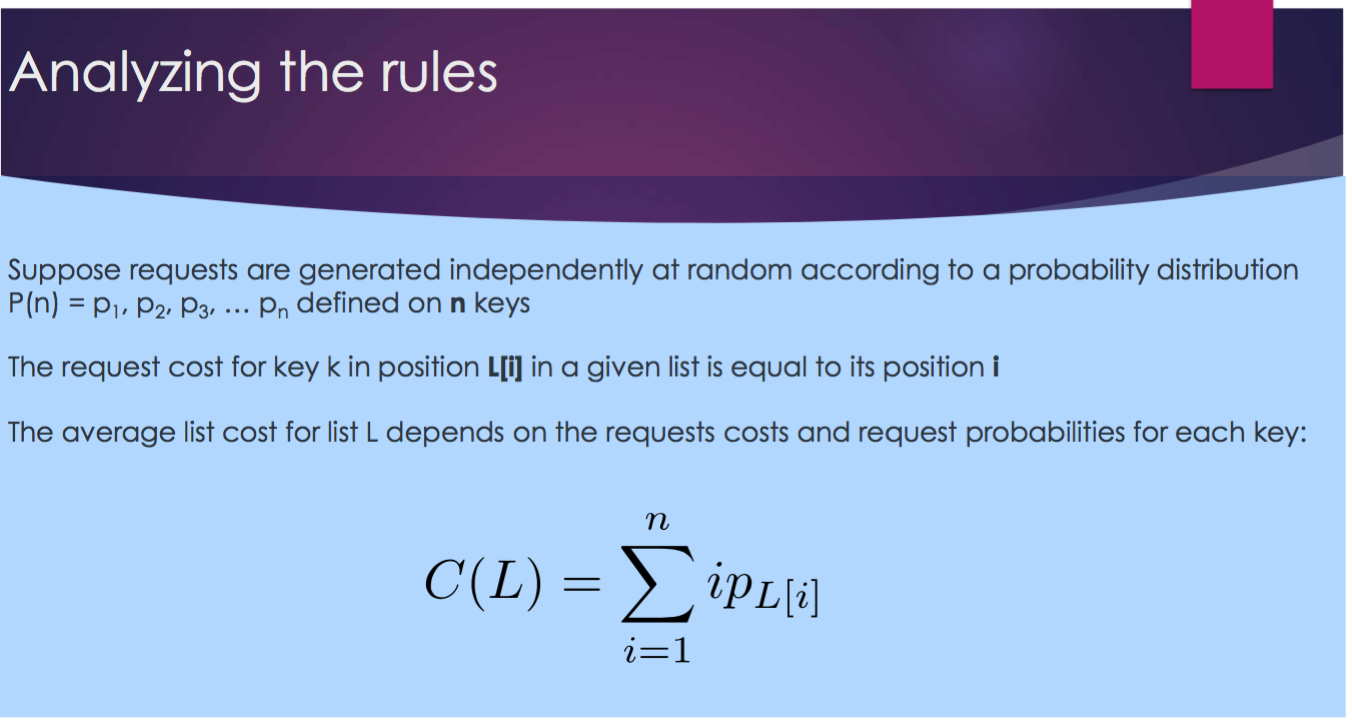 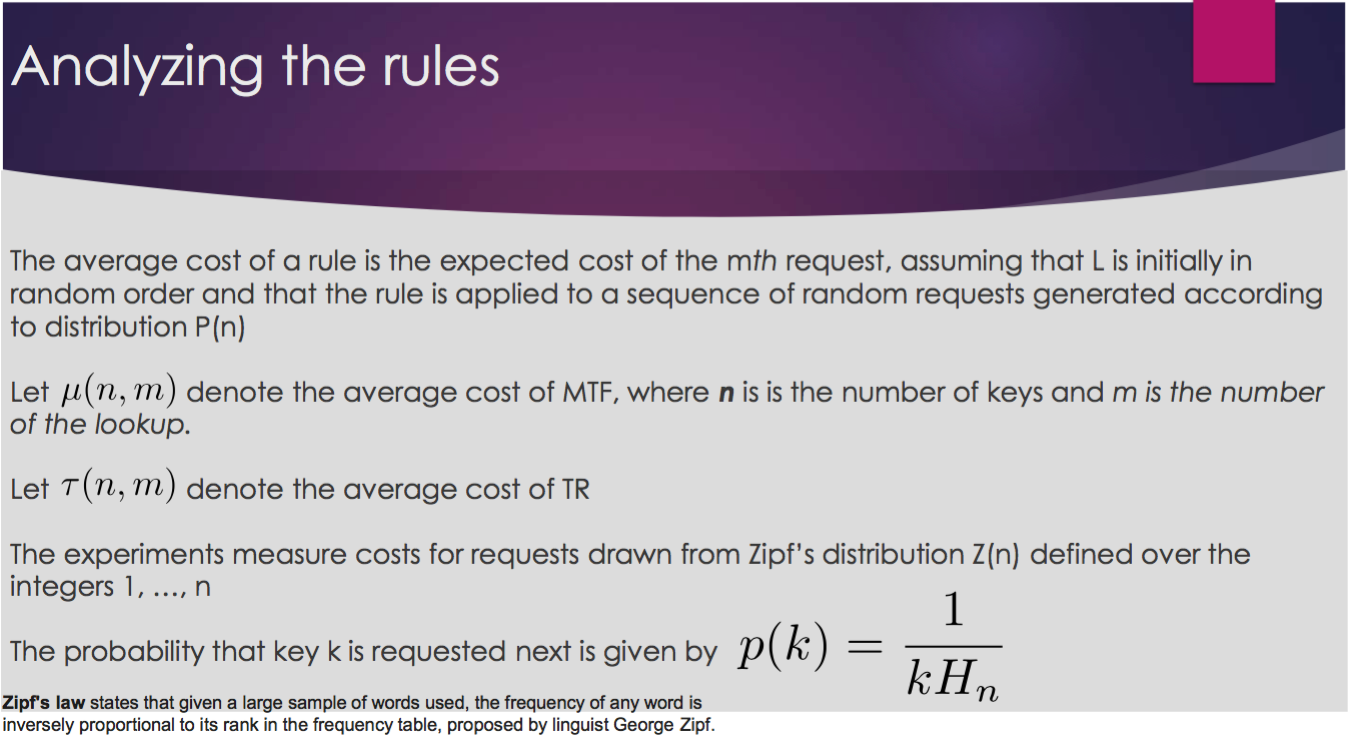

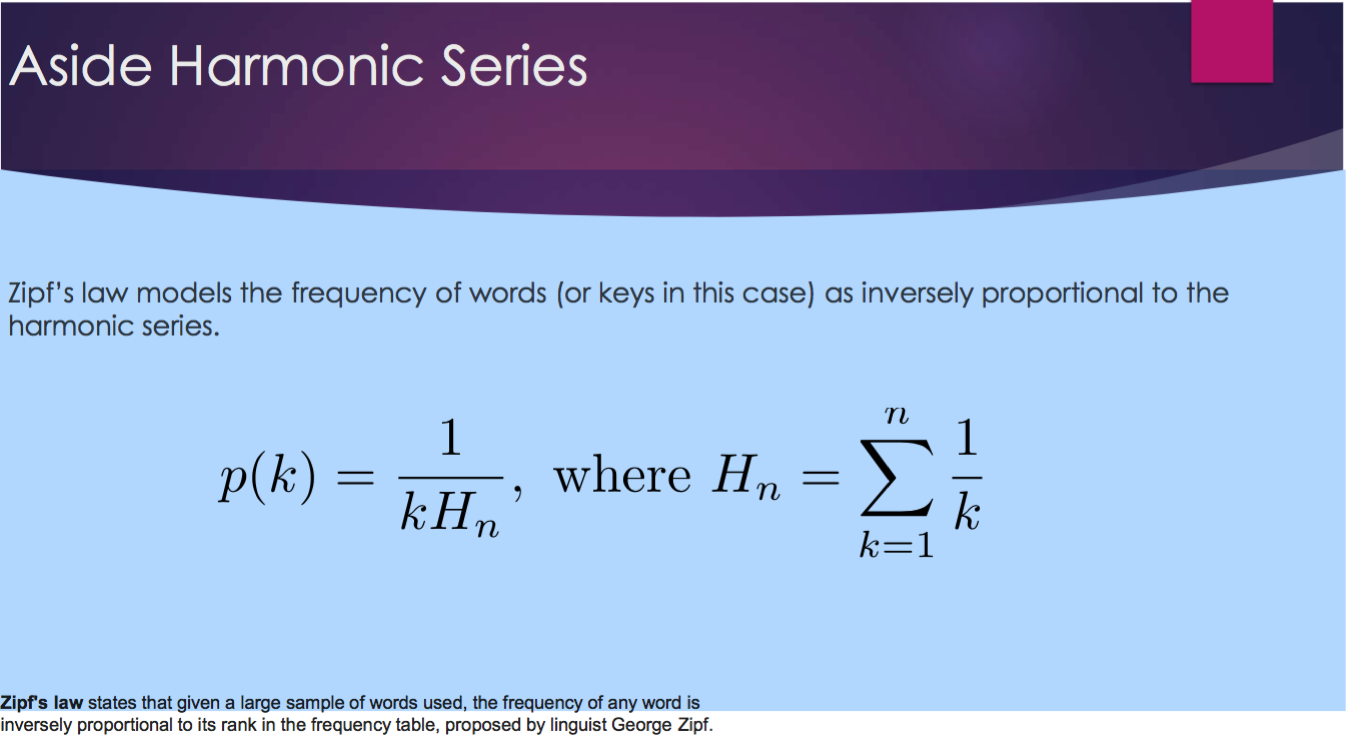 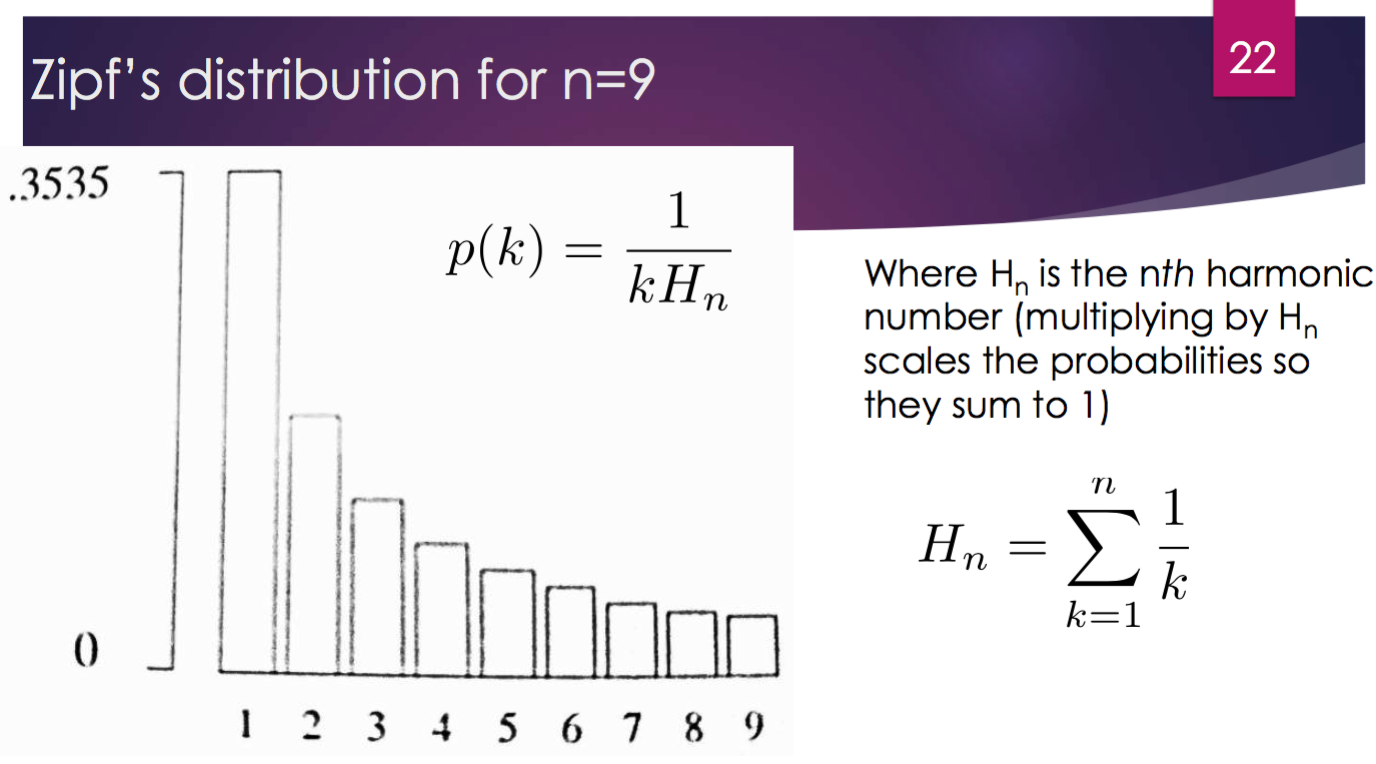 

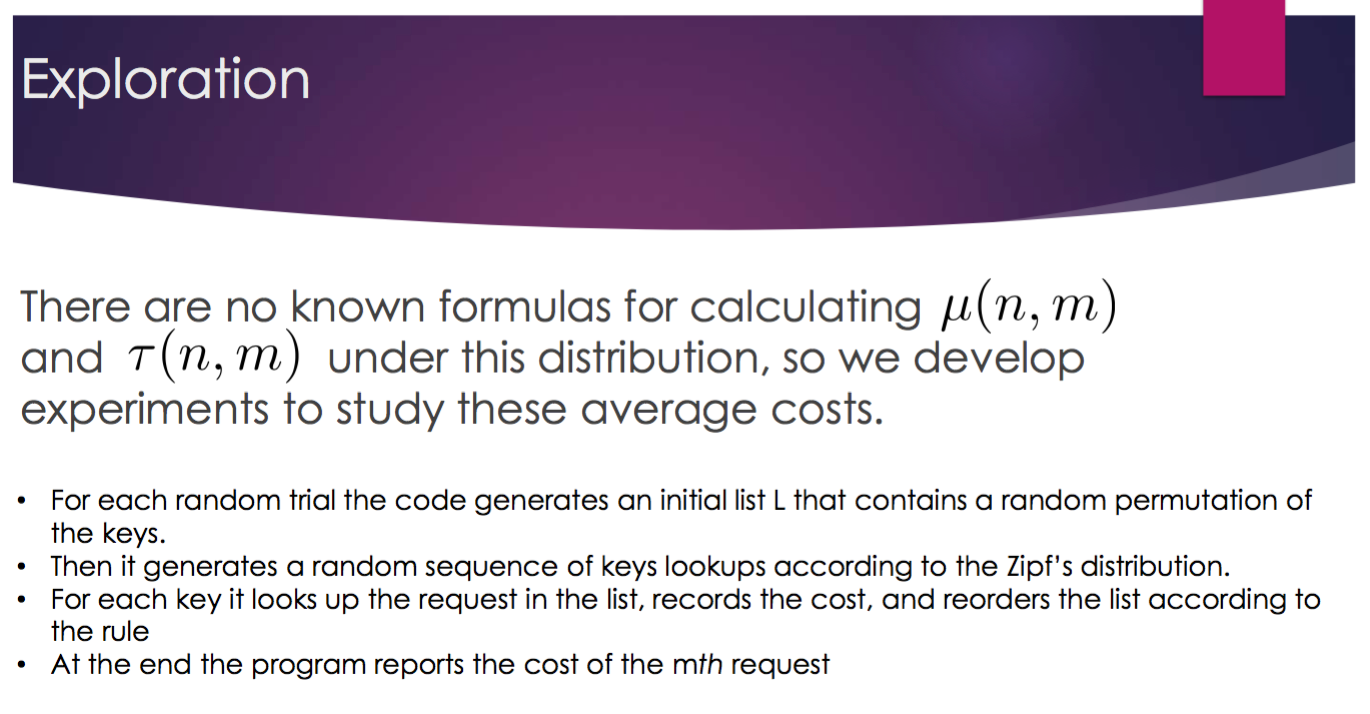 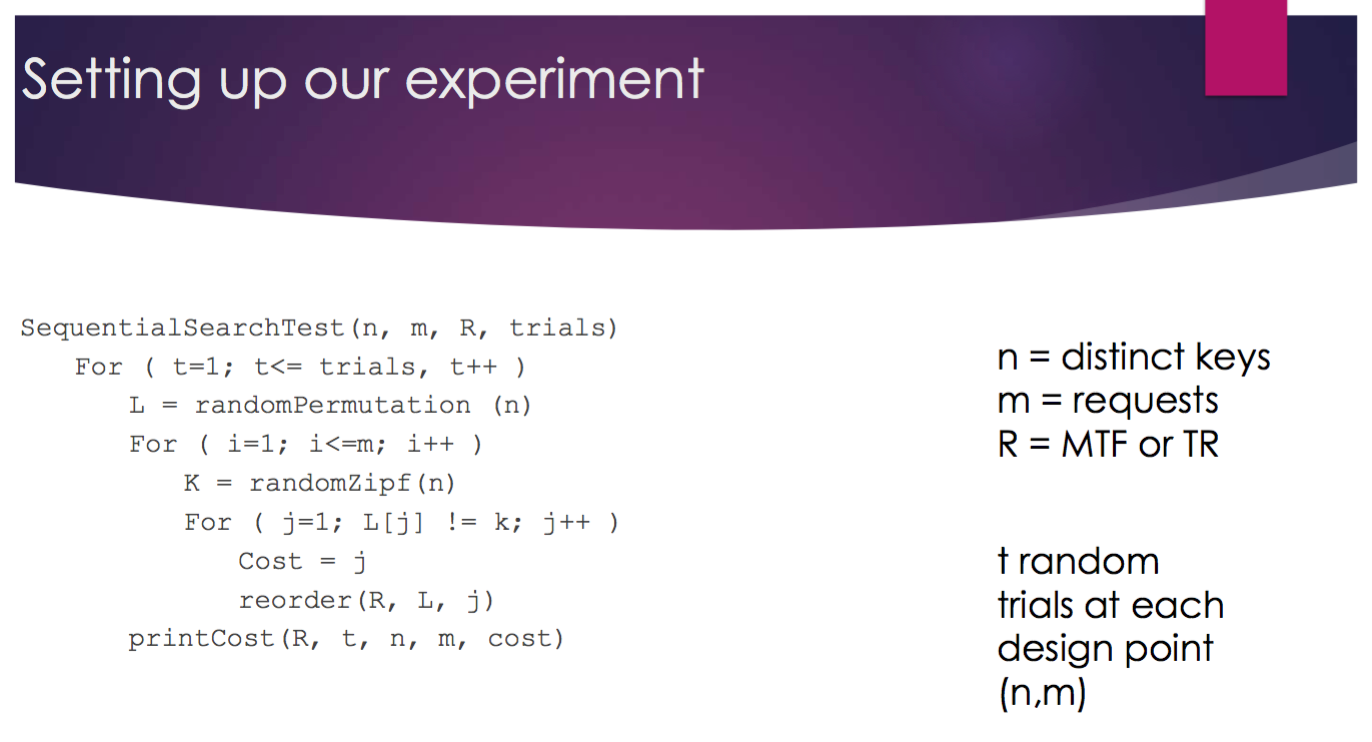  

We begin by establishing a method for sampling from a Zipfian distribution.

% set a convenient format for printing values
format shortG

% set the number of "keys" considered in each list of keys
% the so-called keys will be integers 1-numberOfKeys
numberOfKeys = 10;

% allocate space for storing the relative probabilities of the keys
zipfValues = zeros(numberOfKeys, 1);

% establish the probability for each key value,
% using the zipf() function defined in the functions section
% at the bottom of this livescript
for i = 1:1:numberOfKeys
    zipfValues(i) = zipf(i, numberOfKeys);
end

% check our calculations: the sum of the calculated zipf values
% should be (approximately) 1
sum(zipfValues)

ans =             1


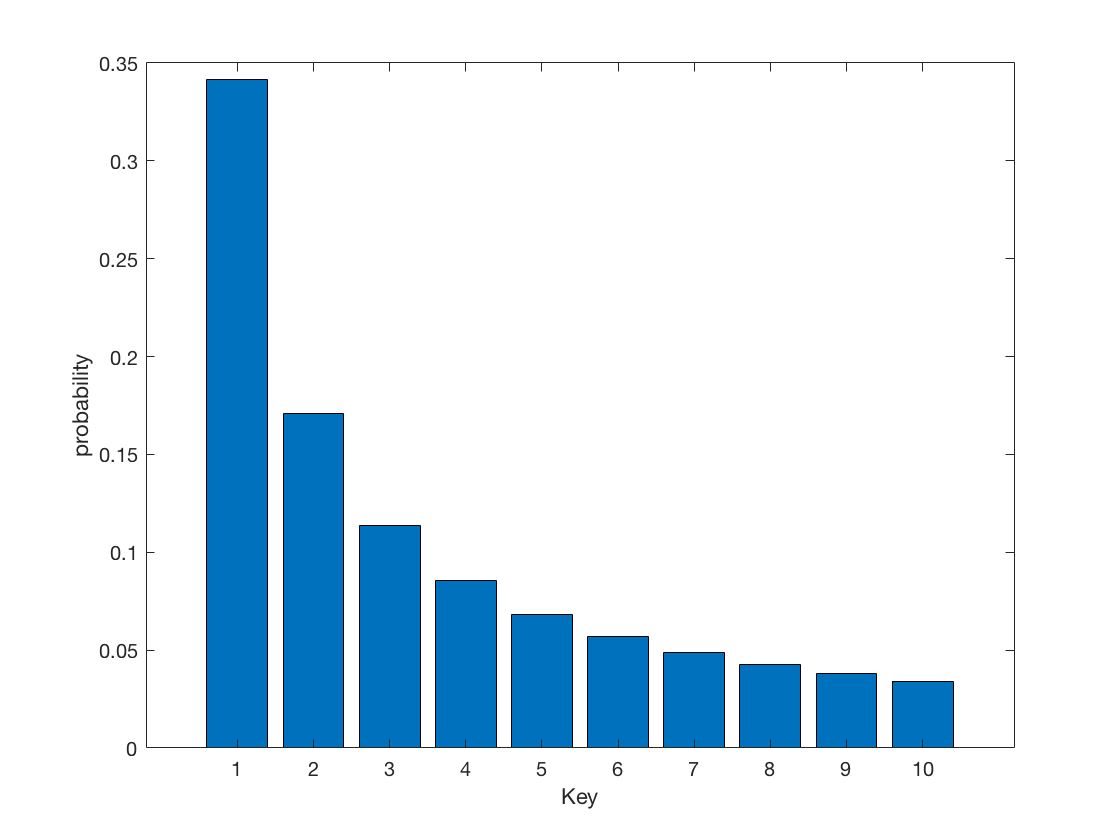

% and take a look at the probability density function (pdf)
bar(zipfValues)
xlabel('Key')
ylabel('probability')

## Sampling from a Zipf Distribution

In this section we generate pseudo-random integers sampled from a Zipf distribution of integers, using a rejection method (as discussed in Kalos & Whitlock (2008), Section 3.5, pp 53–61).

Notice that the pdf has a maximum value of approx 0.34142:

maxProb = max(zipfValues)

maxProb =       0.34142


We effect a sampling of the Zipf distribution by first picking an integer x randomly from 1 to numberOfKeys, then a second random number y = maxProb * rand(0,1). If y ≤ zipfValues(x), we keep x as one of our randomly-generated values, else we discard it and repeat the process.

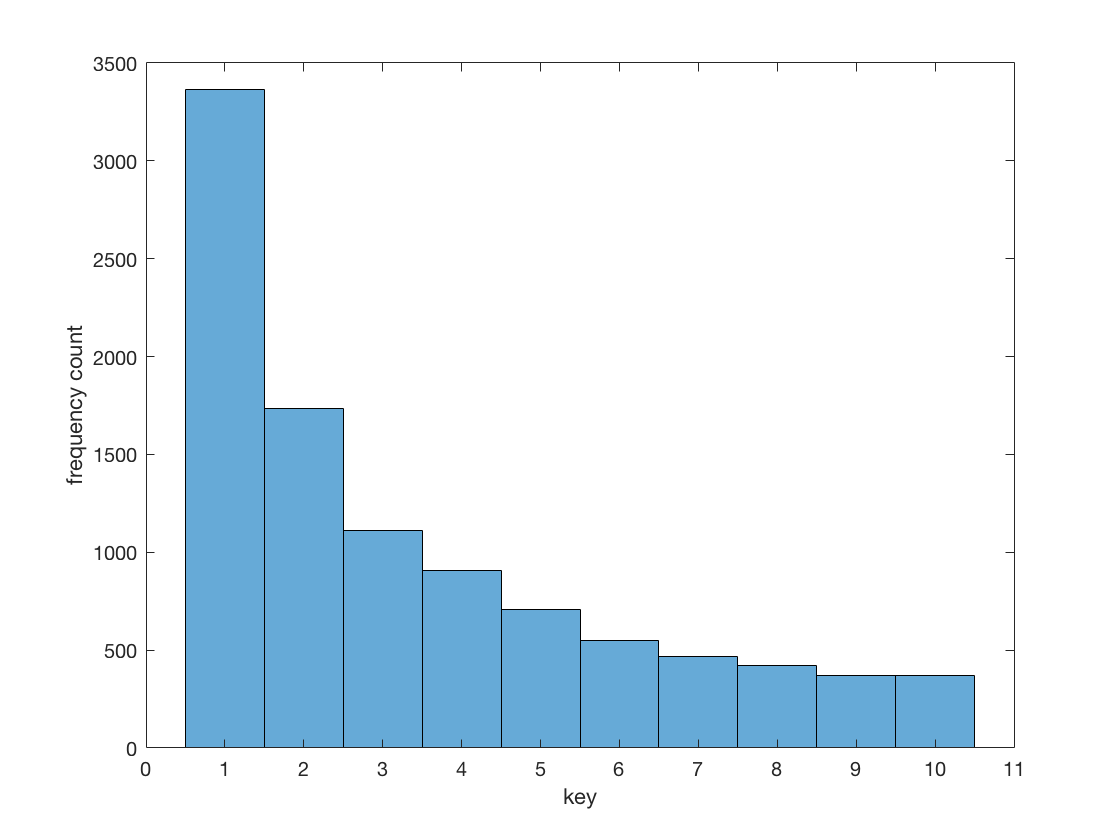

% desired sample size
desiredNumberOfValues = 10000;

% number of values in sample so far:
actualNumberOfValues = 0;

% allocate space for the eventual sample:
sampleOfValues = zeros(desiredNumberOfValues, 1);

% perform the rejection-based sampling
while actualNumberOfValues < desiredNumberOfValues
    % pick a random key
    rand01 = randi(numberOfKeys);
    % pick a random real from (0, maxProb)
    rand02 = maxProb * rand();
    % determine if initial rand01 should be kept or rejected
    if rand02 <= zipfValues(rand01)
        actualNumberOfValues = actualNumberOfValues + 1;
        sampleOfValues(actualNumberOfValues) = rand01;
    end
end

% take a look at the distribution created
histogram(sampleOfValues)
xlabel('key')
ylabel('frequency count')

% express the distribution in terms of probabilities:
sampleOfValuesProbabilities = zeros(numberOfKeys, 1);
for i = 1:numberOfKeys
    sampleOfValuesProbabilities(i) = sum(sampleOfValues(:)==i);
end
sampleOfValuesProbabilities = ...
    sampleOfValuesProbabilities/sum(sampleOfValuesProbabilities)

sampleOfValuesProbabilities =        0.3363
       0.1733
       0.1109
       0.0907
       0.0706
       0.0551
       0.0465
       0.0423
       0.0372
       0.0371


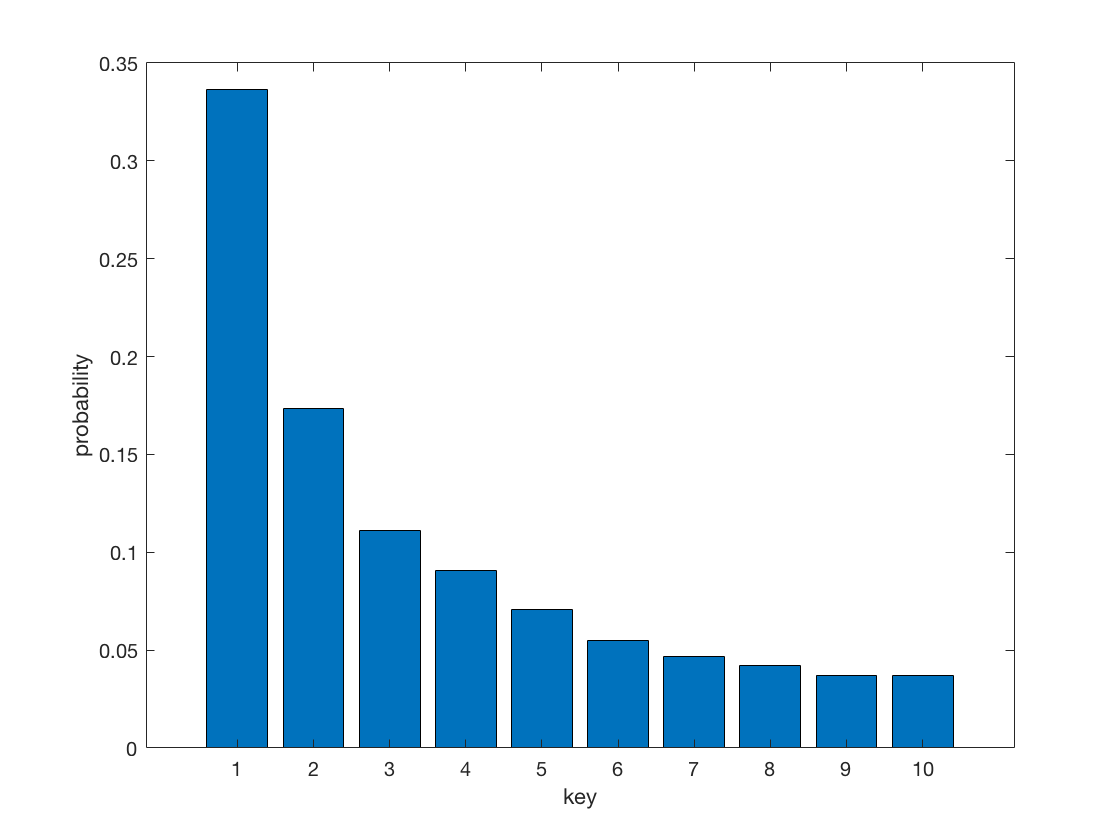

% take a look at the probability distribution created
bar(sampleOfValuesProbabilities)
xlabel('key')
ylabel('probability')

And we can take a quick look at the difference between the empirically-generated probabilities and the theoretical ones, standardized over the theoretical probabilities. The differences tend to have a max absolute value less than about 2% over time:

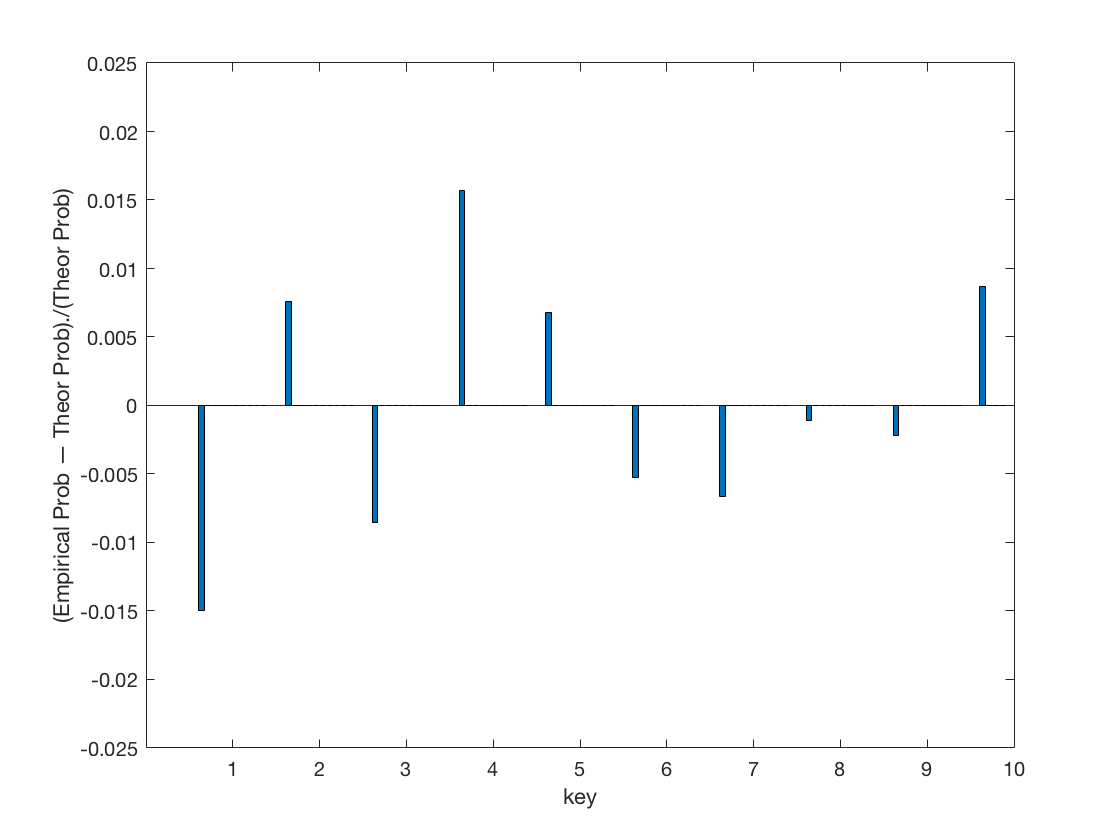

% take a look at the difference between the empirical distribution values
% and the theoretical Zipf distribution values, std'ized by the theoretical values:
bar((sampleOfValuesProbabilities-zipfValues)/zipfValues);
xlabel('key')
ylabel('(Empirical Prob — Theor Prob)./(Theor Prob)')
axis([0 10 -0.025 0.025])

The zipf(j, n) function below returns the Zipfian distribution-based probability of the jth-ranked item of a collection of *n* possible items:

function p = zipf(j, n)
% Returns p(j) = 1/(j H_n), where H_n = sum(1/k) for k = 1 to n,
% a standardized pdf version of Zipf's Law.
% Zipf's Law states that "given some corpus of natural language utterances,
% the frequency of any word is inversely proportional to its rank in the
% frequency table" [https://en.wikipedia.org/wiki/Zipf%27s_law.
syms k;
p = 1/(j * symsum(1/k, k, [1 n]));
end